# Geotherms with erosion and deposition

based on discussion in [Heat Generation and Transport in the Earth](https://www.cambridge.org/core/books/heat-generation-and-transport-in-the-earth/09CE73434DC1C928FFC4B41DA9AD72E2) by Jaupart and Mareschal

clear, clc, close all
set_demo_defaults

A relatively simple example of advective-conductive heat transport is given by the response of the geotherm to both erosion and deposition. Here we consider the following problem

$\frac{\partial T}{\partial t} -D \frac{\partial^2 T}{\partial z^2} = f_s$ on the domain $z\in \left[z_s,\,\infty\right)$ and the boundary condition $T(z_s) = T_0$.

Here $z$ is the depth below the initial surface and $z_s(t)$ is the current location of the surface. For a constant erosion or deposition rate, $v_s$, the surface location is given by $z_s = v_s t$. Because $z$ is the depth, errosion leads to a positive surface velocity$v_s<0$ and deposition leads to a negative surface velocity $v_s<0$. 

To understand how this gives rise to heat advection consider a change in coordinates to a reference frame attached to the surface

$x = z-z_s(t)=z-v_st$.

In this new variable the surface is always located at $x=0$. 

We denote the temperature in this new variable as $\theta(x(z,t),t) \equiv T(z,t)$ and transform the partial deivatives as follows


$$\frac{\partial T}{\partial t} = \frac{\mbox{d} T}{\mbox{d} t} \equiv  \frac{\mbox{d} \theta}{\mbox{d} t} =  \frac{\partial \theta}{\partial t}+\frac{\partial \theta}{\partial x}\frac{\partial x}{\partial t} = \frac{\partial \theta}{\partial t} -v_s\frac{\partial \theta}{\partial x}  $$



$$\frac{\partial^2T}{\partial t^2}\equiv\frac{\partial^2\theta}{\partial z^2} = \left(\frac{\partial x}{\partial z}\right)^2\frac{\partial^2\theta}{\partial x^2} = \frac{\partial^2\theta}{\partial x^2} $$


so that we have an advection-conduction equation


$$\frac{\partial \theta}{\partial t} - v_s \frac{\partial \theta}{\partial x} - D\frac{\partial^2 \theta}{\partial x^2} = f_s$$


in the coordinate attached to the surface. We see that errosion, $v_s>0$, leads to advection in the negative $x$-direction and hence transport of heat from depth towards the surface. In contrast, deposition, $v_s<0$, leads to transport in the positive $x$-direction and hence downward advection of cooler surface temperatures.

However, it is customary to write the advection diffusion equation without a negative sign in front of the advection term. To change the sign we introduce the erosion rate, $v_e = -v_s$, so that we recover the standard advection diffusion equation.

$\frac{\partial \theta}{\partial t} + v_e \frac{\partial \theta}{\partial x} - D\frac{\partial^2 \theta}{\partial x^2} = f_s$.

## Analytic solution

However, it is customary to write the advection diffusion equation derived abve without a negative sign in front of the advection term. To change the sign we introduce the erosion rate, $v_e = -v_s$, so that we recover the standard advection diffusion equation.


$$\frac{\partial \theta}{\partial t} + v_e \frac{\partial \theta}{\partial x} - D\frac{\partial^2 \theta}{\partial x^2} = f_s$$


[Jaupart and Mareschal (2014)](https://www.cambridge.org/core/books/heat-generation-and-transport-in-the-earth/09CE73434DC1C928FFC4B41DA9AD72E2) give the analytic solution for a half-space without heat production, $f_s=0$, and constant erosion/deposition and and intial geotherm with constant gradient, $T(x,0) = \Gamma x$, as


$$T(x,t) = \Gamma(x-v_et)+\frac{\Gamma}{2}(x+v_et)e^{v_ex/\kappa}\mbox{erfc}\left(\frac{x+v_et}{\sqrt{4 D t}}\right)+\frac{\Gamma}{2}(v_et-x)\mbox{erfc}\left(\frac{x-v_et}{\sqrt{4Dt}}\right)$$


which can be used to investigate the effect of errosion/deposition on the near surface geotherm.

yr2s = 60^2*24*365.25;
Gamma = 25/1000;    % geothermal gradient [C/m]
kappa = 1e-6;       % thermal diffusivity [m^2/s]

T0 = @(z) Gamma*z;
T = @(z,t,ve) Gamma*(z-ve*t)+Gamma/2*(z+ve*t).*exp(ve*z/kappa).*erfc((z+ve*t)./(sqrt(4*kappa*t)))+Gamma/2*(ve*t-z).*erfc((z-ve*t)./(2*sqrt(kappa*t)));
Nz=100;
z = linspace(0,5e3,Nz);

## **Geotherm with errosion**

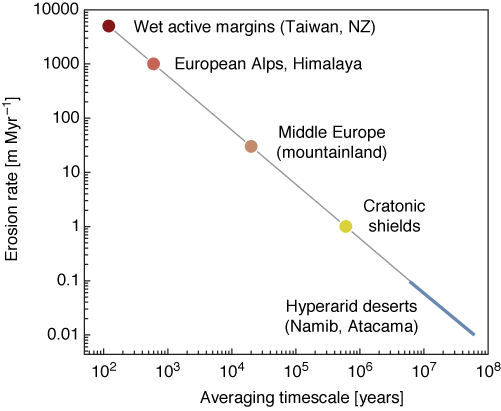

Errosion rates vary widely but are typically given in terms of m/Myr's, see figure. Here we will investigate the effect of very rapid deposition and errosion on the geotherm, because this model is inly valid for short (but potentially significant) perturbations to an otherwise steady geotherm. 

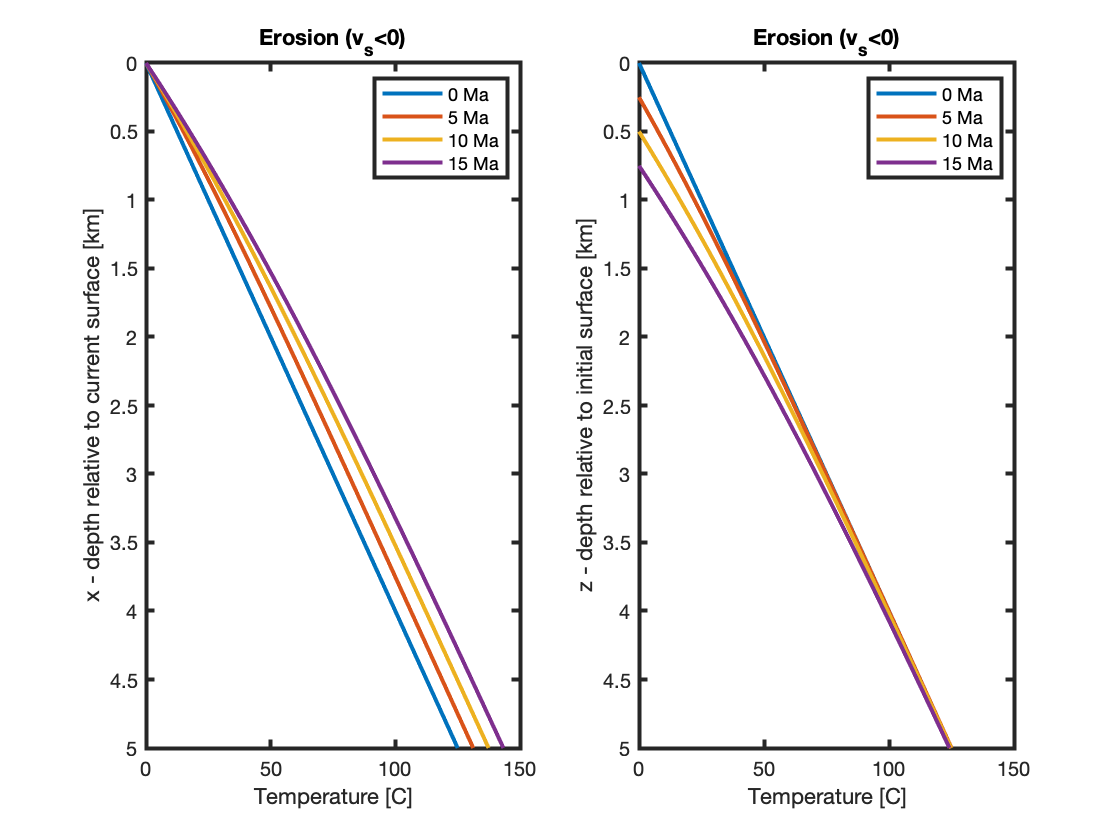

v_erosion = -5e3/1e6/yr2s;   % erosion rate [m/s]
t = [5 10 15]*1e4*yr2s;
[zz,tt] = meshgrid(z,t);

zI = -v_erosion*t;
figure
subplot 121
plot(T0(z),z/1e3), hold on
for i = 1:length(zI); plot(T(z,t(i),v_erosion),(z)/1e3); end
hold off
set(gca, 'YDir','reverse')
xlabel('Temperature [C]')
ylabel('x - depth relative to current surface [km]')
ylim([0 5])
legend('0 Ma','5 Ma','10 Ma','15 Ma')
title 'Erosion (v_s<0)'

subplot 122
plot(T0(z),z/1e3), hold on
for i = 1:length(zI); plot(T(z,t(i),v_erosion),(z+zI(i))/1e3); end
hold off
set(gca, 'YDir','reverse')
xlabel('Temperature [C]')
ylabel('z - depth relative to initial surface [km]')
ylim([0 5])
legend('0 Ma','5 Ma','10 Ma','15 Ma')
title 'Erosion (v_s<0)'

## Geotherm with deposition

I currently do not have plot with deposition rates - looking for it.

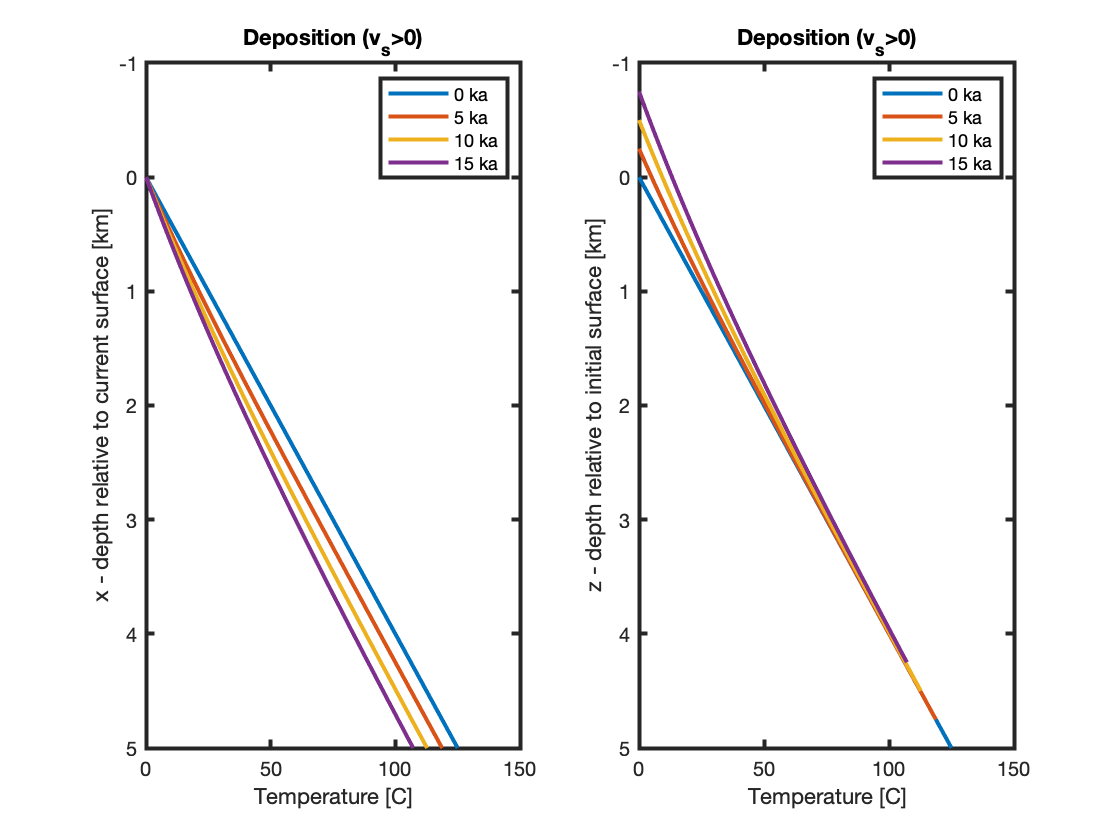

v_depo = 5e3/1e6/yr2s;   % deposition rate [m/s]
zI = -v_depo*t;
t = [5 10 15]*1e4*yr2s;
[zz,tt] = meshgrid(z,t);

figure
subplot 121
plot(T0(z),z/1e3), hold on
for i = 1:length(zI)
plot(T(z,t(i),v_depo),(z)/1e3)
end
set(gca, 'YDir','reverse')
xlabel('Temperature [C]')
ylabel('x - depth relative to current surface [km]')
ylim([-1 5])
title 'Deposition (v_s>0)'
legend('0 ka','5 ka','10 ka','15 ka')

subplot 122
plot(T0(z),z/1e3), hold on
for i = 1:length(zI)
plot(T(z,t(i),v_depo),(z+zI(i))/1e3)
end
set(gca, 'YDir','reverse')
xlabel('Temperature [C]')
ylabel('z - depth relative to initial surface [km]')
ylim([-1 5])
title 'Deposition (v_s>0)'
legend('0 ka','5 ka','10 ka','15 ka')